# Appendix - Exercise 1

# Tuning of Gain-Scheduled Three-Loop Autopilot

This example uses the command [*systune*](https://www.mathworks.com/help/releases/R2022b/control/ref/lti.systune.html) to generate smooth gain schedules for a three-loop autopilot.

## Airframe Model and Three-Loop Autopilot 

This example uses a three-degree-of-freedom model of the pitch axis dynamics of an airframe. The states are the Earth coordinates $\left(X_e ,Z_e \right)$, the body coordinates $\left(u,w\right)$, the pitch angle $\theta$, and the pitch rate $q=\dot{\theta}$. The following figure summarizes the relationship between the inertial and body frames, the flight path angle $\gamma$, the incidence angle $\alpha$, and the pitch angle $\theta$. 

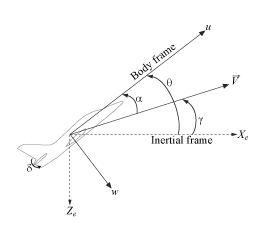

We use a classic three-loop autopilot structure to control the flight path angle $\gamma$. This autopilot adjusts the flight path by delivering adequate bursts of normal acceleration $a_z$ (acceleration along $w$). In turn, normal acceleration is produced by adjusting the elevator deflection $\delta$ to cause pitching and vary the amount of lift. The autopilot uses Proportional-Integral (PI) control in the pitch rate loop $q$ and proportional control in the $a_z$ and $\gamma$ loops. The closed-loop system (airframe and autopilot) are modeled in Simulink.

open_system('GSAutopilot')

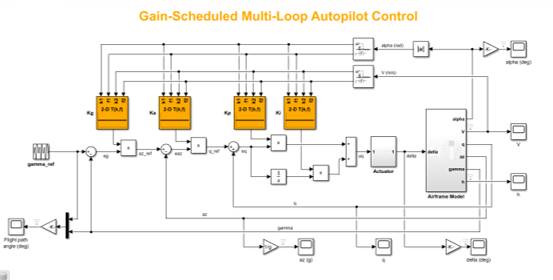

## Autopilot Gain Scheduling

The airframe dynamics are nonlinear and the aerodynamic forces and moments depend on speed $V$ and incidence $\alpha$. To obtain suitable performance throughout the $\left(\alpha ,V\right)$ flight envelope, the autopilot gains must be adjusted as a function of $\alpha$ and $V$ to compensate for changes in plant dynamics. This adjustment process is called "gain scheduling" and $\alpha ,V$ are called the scheduling variables. In the Simulink model, gain schedules are implemented as look-up tables driven by measurements of  $\alpha$ and $V$.

Gain scheduling is a linear technique for controlling nonlinear or time-varying plants. The idea is to compute linear approximations of the plant at various operating conditions, tune the controller gains at each operating condition, and swap gains as a function of operating condition during operation. Conventional gain scheduling involves three major steps:

- Trim and linearize the plant at each operating condition

- Tune the controller gains for the linearized dynamics at each operating condition

- Reconcile the gain values to provide smooth transition between operating conditions.

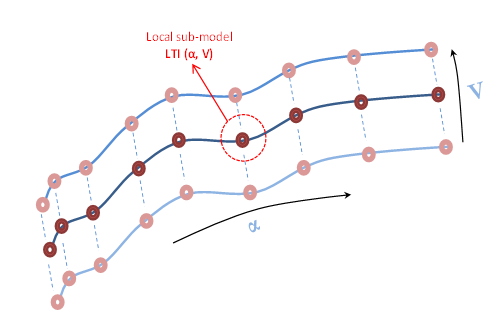

In this example, we combine Steps 2 and 3 by parameterizing the autopilot gains as first-order polynomials in $\alpha ,V$ and directly tuning the polynomial coefficients for the entire flight envelope. This approach eliminates Step 3 and guarantees smooth gain variations as a function of $\alpha$ and $V$. Moreover, the gain schedule coefficients can be automatically tuned with *systune*.

## Trimming and Linearization

Assume that the incidence $\alpha$ varies between -20 and 20 degrees and that the speed $V$ varies between 700 and 1400 m/s. When neglecting gravity, the airframe dynamics are symmetric in $\alpha$ so consider only positive values of $\alpha$. Use a 5-by-9 grid of linearly spaced $\left(\alpha ,V\right)$ pairs to cover the flight envelope:

nA = 5;  % number of alpha values
nV = 9;  % number of V values
[alpha,V] = ndgrid(linspace(0,20,nA)*pi/180,linspace(700,1400,nV));

For each flight condition $\left(\alpha ,V\right)$, linearize the airframe dynamics at trim (zero normal acceleration and pitching moment). This requires computing the elevator deflection $\delta$ and pitch rate $q$ that result in steady $w$ and $q$. To do this, first isolate the airframe model in a separate Simulink model.

model = 'AirframeModelTRIM';
open_system(model)

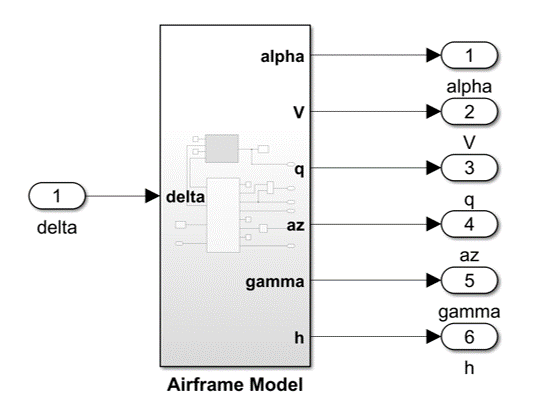q

## Find array of trim conditions

Use [*operspec*](https://www.mathworks.com/help/releases/R2022b/slcontrol/ug/operspec.html) to specify the trim condition, use [*findop*](https://www.mathworks.com/help/releases/R2022b/slcontrol/ug/findop.html) to compute the trim values of $\delta$ and $q$, and linearize the airframe dynamics for the resulting operating point. See the [Trim and Linearizing an Airframe](https://www.mathworks.com/help/releases/R2022b/slcontrol/ug/trimming-and-linearizing-an-airframe.html) example in Simulink Control Design for details. Repeat these steps for the 45 flight conditions $\left(\alpha ,V\right)$.

% Compute trim condition for each (alpha,V) pair
clear op
% Create an operating point specification object
opspec = operspec(model,nA*nV);

for ct=1:nA*nV
   % Set the constraints on the states in the model.
   % Xe,Ze: known, not steady
   opspec(ct).States(1).Known = [true;true];
   opspec(ct).States(1).SteadyState = [false;false];
   % theta: known, not steady
   opspec(ct).States(2).Known = true;
   opspec(ct).States(2).SteadyState = false;
   % u,w: unknown, w steady
   opspec(ct).States(3).Known = [false;false];
   opspec(ct).States(3).SteadyState = [false;true];
   % q: unknown, steady
   opspec(ct).States(4).Known = false;
   opspec(ct).States(4).SteadyState = true;
   
   % Set the constraints on the outputs in the model.
   % Output (1) - alpha
   opspec(ct).Outputs(1).y = alpha(ct);
   opspec(ct).Outputs(1).Known = true;
   % Output (2) - V
   opspec(ct).Outputs(2).y = V(ct);
   opspec(ct).Outputs(2).Known = true; 
end
opspec = reshape(opspec,[nA nV]);

Trim the model for the given specifications.

opt = findopOptions('DisplayReport','off');
op = findop(model,opspec,opt);

## Linearize the model at trim conditions

G = linearize(model,op);
G.u = 'delta';
G.y = {'alpha' 'V' 'q' 'az' 'gamma' 'h'};
G.SamplingGrid = struct('alpha',alpha,'V',V);

This produces a 5-by-9 array of linearized plant models at the 45 flight conditions $\left(\alpha ,V\right)$. The plant dynamics vary substantially across the flight envelope.

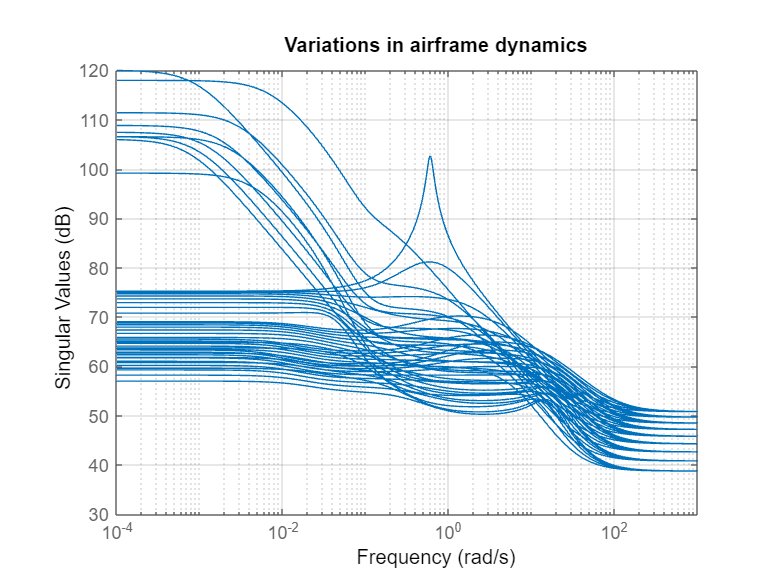

sigma(G)
title('Variations in airframe dynamics')
grid on

## Define Tunable Gain Surfaces

The autopilot consists of four gains $K_p ,K_i ,K_a ,K_g$ to be "scheduled" (adjusted) as a function of $\alpha$ and $V$. Practically, this means tuning 88 values in each of the corresponding four look-up tables. Rather than tuning each table entry separately, parameterize the gains as a two-dimensional gain surfaces, for example, surfaces with a simple multi-linear dependence on $\alpha$ and $V$:

#### 
$$K\left(\alpha ,V\right)=K_0 +K_1 \alpha +K_2 V+K_3 \alpha V$$


This cuts the number of variables from 88 down to 4 for each lookup table. Use the |tunableSurface| object to parameterize each gain surface. Note that:

- **TuningGrid** specifies the "tuning grid" (design points). This grid should match the one used for linearization but needs not match the loop-up table breakpoints

- **ShapeFcn** specifies the basis functions for the surface parameterization ($\alpha ,V$, and $\alpha V$)

Each surface is initialized to a constant gain using the tuning results for $\alpha$ = 10 deg and $V$ = 1050 m/s (mid-range design).

TuningGrid = struct('alpha',alpha,'V',V);
ShapeFcn = @(alpha,V) [alpha,V,alpha*V];

Kp = tunableSurface('Kp', 0.1, TuningGrid, ShapeFcn);
Ki = tunableSurface('Ki', 2, TuningGrid, ShapeFcn);
Ka = tunableSurface('Ka', 0.001, TuningGrid, ShapeFcn);
Kg = tunableSurface('Kg', -1000, TuningGrid, ShapeFcn);

Next create an **slTuner** interface for tuning the gain surfaces. Use block substitution to replace the nonlinear plant model by the linearized models over the tuning grid. Use **setBlockParam** to associate the tunable gain surfaces **Kp, Ki, Ka, Kg** with the Interpolation blocks of the same name.

BlockSubs = struct('Name','GSAutopilot/Airframe Model','Value',G);
ST0 = slTuner('GSAutopilot',{'Kp','Ki','Ka','Kg'},BlockSubs);

% Register points of interest 
ST0.addPoint({'az_ref','az','gamma_ref','gamma','delta'})

% Parameterize look-up table blocks
ST0.setBlockParam('Kp',Kp,'Ki',Ki,'Ka',Ka,'Kg',Kg);

## **Autopilot** **Tuning**

**systune** can automatically tune the gain surface coefficients for the entire flight envelope. Use **TuningGoal** objects to specify the performance objectives:

- $\gamma$ loop: Track the setpoint with a 1 second response time, less than 2% steady-state error, and less than 30% peak error.

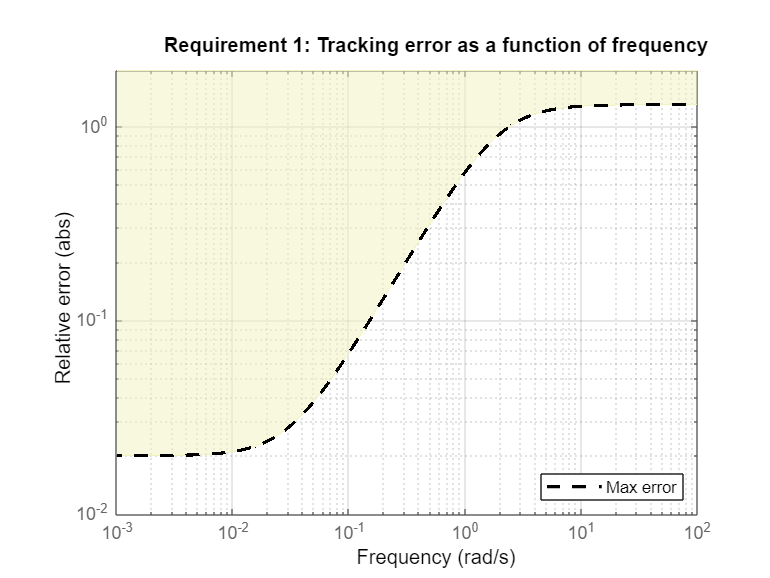

Req1 = TuningGoal.Tracking('gamma_ref','gamma',1,0.02,1.3);
viewGoal(Req1)

- $a_z$ loop: Ensure good disturbance rejection at low frequency (to track acceleration demands) and past 10 rad/s (to be insensitive to measurement noise). The disturbance is injected at the **az_ref** location.

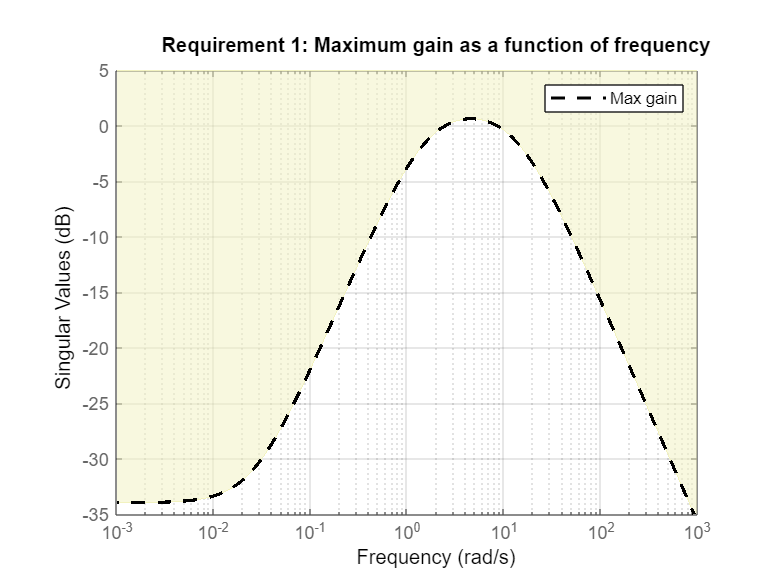

RejectionProfile = frd([0.02 0.02 1.2 1.2 0.1],[0 0.02 2 15 150]);
Req2 = TuningGoal.Gain('az_ref','az',RejectionProfile);
viewGoal(Req2)

- $q$ loop: Ensure good disturbance rejection up to 10 rad/s. The disturbance is injected at the plant input **delta**.

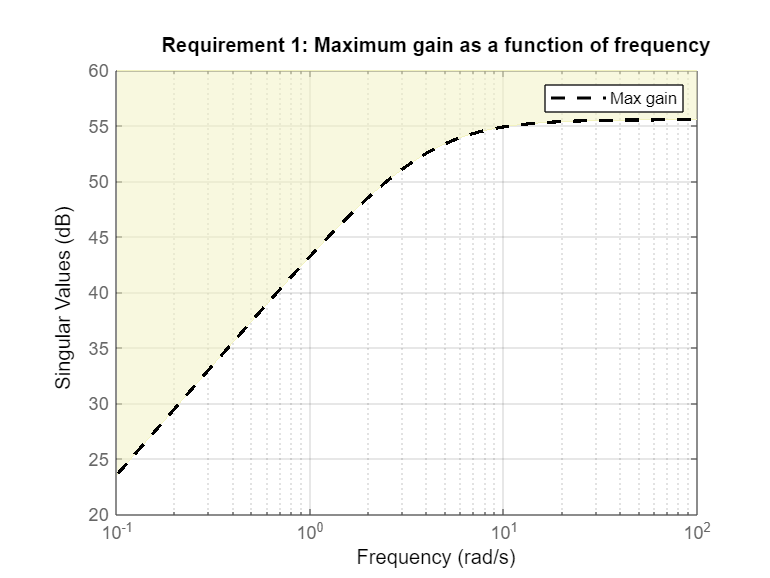

Req3 = TuningGoal.Gain('delta','az',600*tf([0.25 0],[0.25 1]));
viewGoal(Req3)

- Transients: Ensure a minimum damping ratio of 0.35 for oscillation-free transients

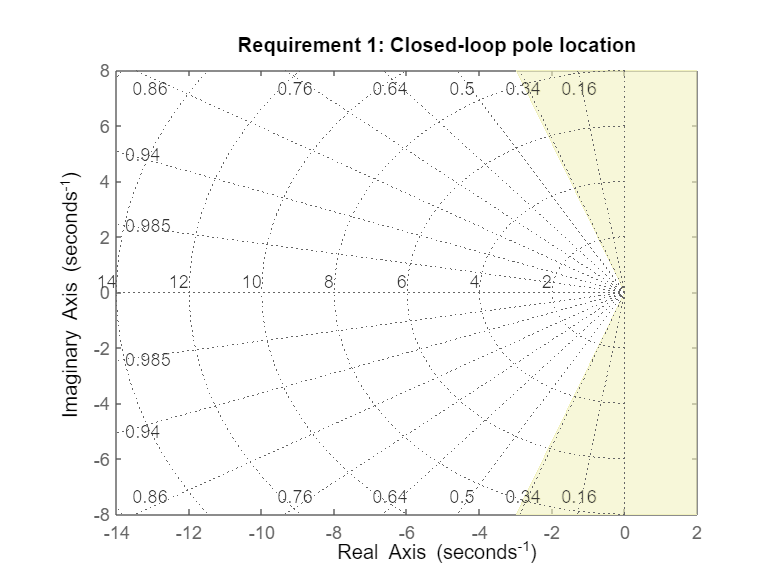

MinDamping = 0.35;
Req4 = TuningGoal.Poles(0,MinDamping);
viewGoal(Req4)

Using **systune**, tune the 16 gain surface coefficients to best meet these performance requirements at all 45 flight conditions.

ST = systune(ST0,[Req1 Req2 Req3 Req4]);

Final: Soft = 1.13, Hard = -Inf, Iterations = 57


The final value of the combined objective is close to 1, indicating that all requirements are nearly met. Visualize the resulting gain surfaces.

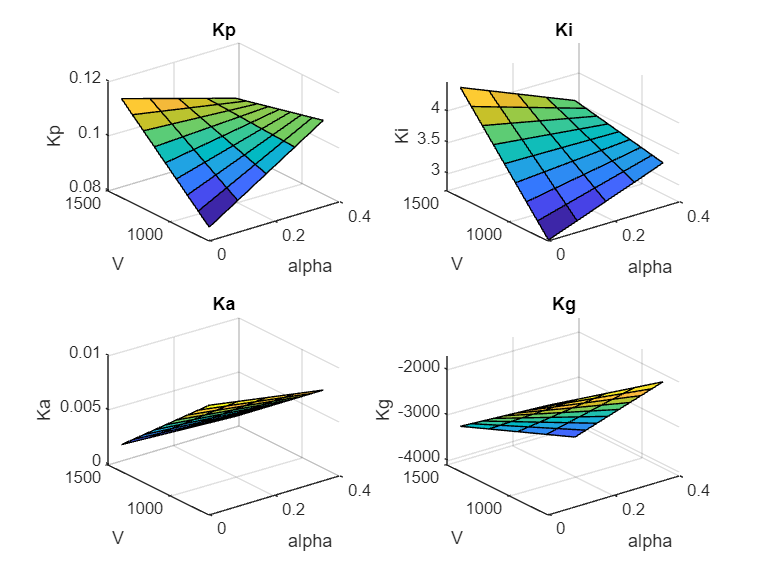

% Get tuned gain surfaces
TGS = getBlockParam(ST);

% Plot gain surfaces
clf
subplot(221), viewSurf(TGS.Kp), title('Kp')
subplot(222), viewSurf(TGS.Ki), title('Ki')
subplot(223), viewSurf(TGS.Ka), title('Ka')
subplot(224), viewSurf(TGS.Kg), title('Kg')

## Validation

First validate the tuned autopilot at the 45 flight conditions considered above. Plot the response to a step change in flight path angle and the response to a step disturbance in elevator deflection.

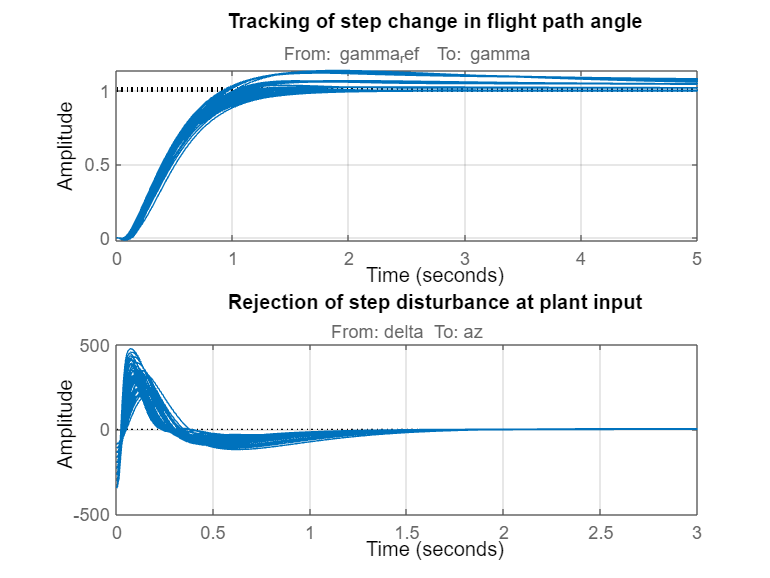

clf
subplot(211), step(getIOTransfer(ST,'gamma_ref','gamma'),5), grid
title('Tracking of step change in flight path angle')
subplot(212), step(getIOTransfer(ST,'delta','az'),3), grid
title('Rejection of step disturbance at plant input')

The responses are satisfactory at all flight conditions. Next validate the autopilot against the nonlinear airframe model. First use **writeBlockValue** to apply the tuning results to the Simulink model. This evaluates each gain surface formula at the breakpoints specified in the two Prelookup blocks and writes the result in the corresponding Interpolation block.

writeBlockValue(ST)

Now simulate the autopilot performance for a maneuver that takes the airframe through a large portion of its flight envelope. The code below is equivalent to pressing the Run button in the Simulink model and inspecting the responses in the Scope blocks.

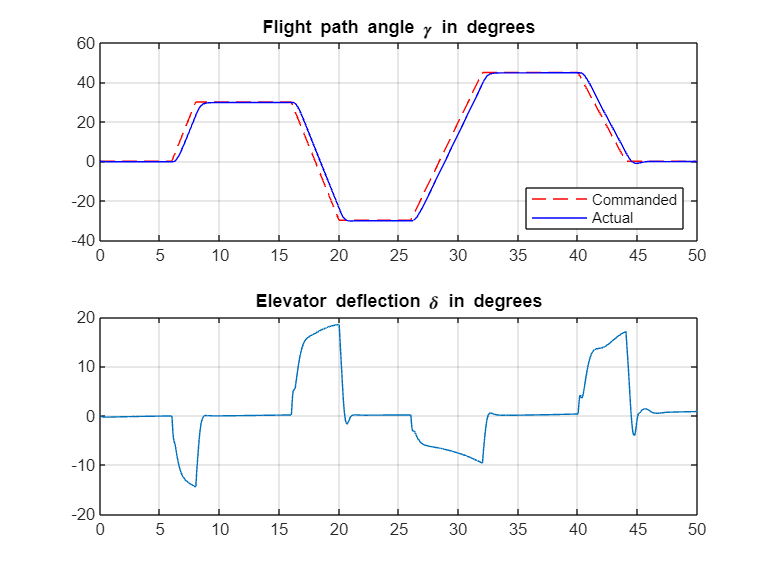

% Initial conditions
h_ini = 1000;
alpha_ini = 0;
v_ini = 700;

% Simulate
SimOut = sim('GSAutopilot', 'ReturnWorkspaceOutputs', 'on');

% Extract simulation data
SimData = get(SimOut,'sigsOut');
Sim_gamma = getElement(SimData,'gamma');
Sim_alpha = getElement(SimData,'alpha');
Sim_V = getElement(SimData,'V');
Sim_delta = getElement(SimData,'delta');
Sim_h = getElement(SimData,'h');
Sim_az = getElement(SimData,'az');
t = Sim_gamma.Values.Time;

% Plot the main flight variables
clf
subplot(211)
plot(t,Sim_gamma.Values.Data(:,1),'r--',t,Sim_gamma.Values.Data(:,2),'b'), grid
legend('Commanded','Actual','location','SouthEast')
title('Flight path angle \gamma in degrees')
subplot(212)
plot(t,Sim_delta.Values.Data), grid
title('Elevator deflection \delta in degrees')

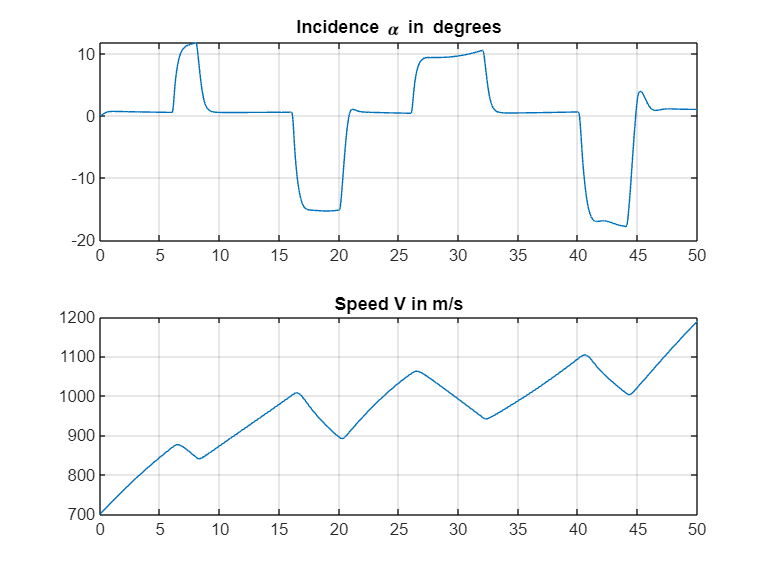

subplot(211)
plot(t,Sim_alpha.Values.Data), grid
title('Incidence \alpha in degrees')
subplot(212)
plot(t,Sim_V.Values.Data), grid
title('Speed V in m/s')

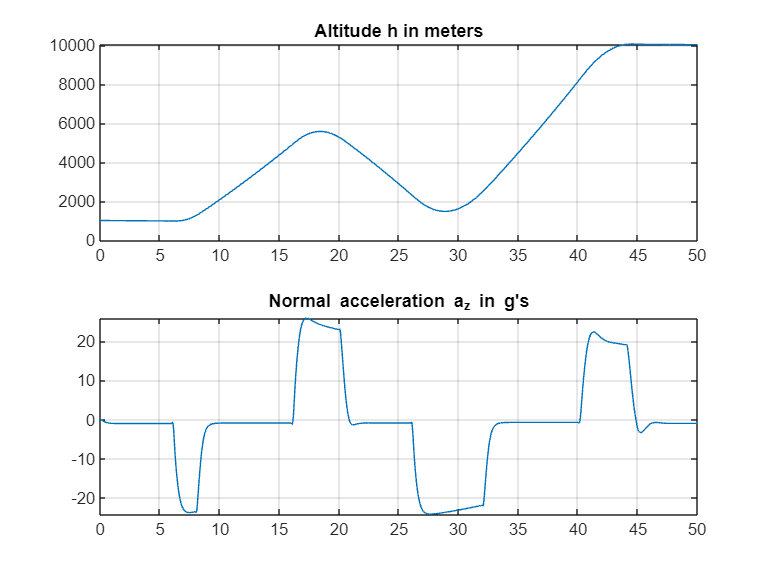

subplot(211)
plot(t,Sim_h.Values.Data), grid
title('Altitude h in meters')
subplot(212)
plot(t,Sim_az.Values.Data), grid
title('Normal acceleration a_z in g''s')

Tracking of the flight path angle profile remains good throughout the maneuver. Note that the variations in incidence $\alpha$ and speed $V$ cover most of the flight envelope considered here ([-20,20] degrees for $\alpha$ and [700,1400] for $V$). And while the autopilot was tuned for a nominal altitude of 3000 m, it fares well for altitude changing from 1,000 to 10,000 m.

The nonlinear simulation results confirm that the gain-scheduled autopilot delivers consistently high performance throughout the flight envelope. The "gain surface tuning" procedure provides simple explicit formulas for the gain dependence on the scheduling variables. Instead of using look-up tables, you can use these formulas directly for an more memory-efficient hardware implementation.